clc, clear all
syms psi q1 q2 q3 q4 q5 l1 l2 l3 l4 l5 a b c ul um un xu yu zu

## Simulacion

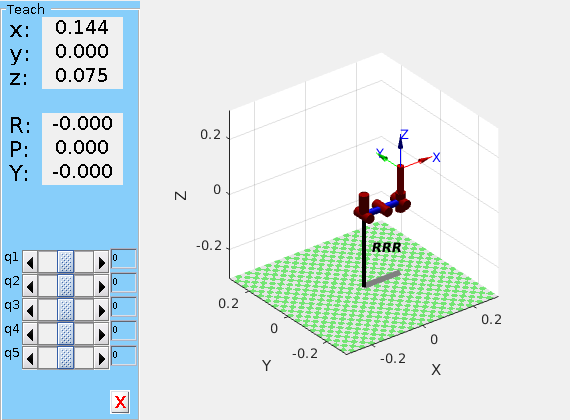

%L1 = -1; L2 = 1; L3 = 1; L4 = 1; L5 = 1;
L1 = -0.042; 
L2 = 0.072; 
L3 = 0.072;
L4 = 0.072;
L5 = 0.045;
% Primer Brazo
Lx(1) = Link([0 L1 0 -pi/2]); 
Lx(2) = Link([0 0 L2 0 ]);
Lx(3) = Link([0 0 L3 0 ]);
Lx(4) = Link([0 0 0 pi/2 ]);
Lx(5) = Link([0 L4+L5 0 0]);

robot = SerialLink(Lx);
robot.name = 'RRR';
robot.teach;

## Denavit-Hartembet Modelo Cinematico


H01 = D_H(q1,-l1,0,-pi/2);

'D_H' is not found in the current folder or on the MATLAB path, but exists in:
    /home/bryan/Proyectos_Matlab/Doctorado/Matlab/Arm5DOF
    /home/bryan/Proyectos_Matlab/Doctorado/Matlab/UAV1Arm5DOF
    /home/bryan/Proyectos_Matlab/Doctorado/Matlab/Modelado Cinematico
    /home/bryan/Proyectos_Matlab/Doctorado/Matlab/Arm4DOF
    /home/bryan/Proyectos_Matlab/Doctorado/Mani2Brazos4DOF
    /home/bryan/Proyectos_Matlab/Doctorado/Matlab/Modelado Dinamico

Change the MATLAB current folder or add its folder to the MATLAB path.

H12 = D_H(q2,0,l2,0);
H23 = D_H(q3,0,l3,0);
H34 = D_H(q4,0,0,pi/2);
H45 = D_H(q5,l4+l5,0,0);


H05 = H01*H12*H23*H34*H45;

hx_1 = simplify(H05(1,4))
hy_1 = simplify(H05(2,4))
hz_1 = simplify(H05(3,4))

hx = a*cos(psi)- b*sin(psi) + hx_1;
hy = a*sin(psi)+ b*cos(psi) + hy_1;
hz = c + hz_1;
q5 = q5;


J=jacobian([hx,hy,hz,q5],[q1,q2,q3,q4,q5]);

J=simplify(J)



## +UAV